y =          0    0.0250    0.0500    0.0750    0.1000    0.1250    0.1500    0.1750    0.2000    0.2250    0.2500    0.2750    0.3000    0.3250    0.3500    0.3750    0.4000    0.4250    0.4500    0.4750    0.5000    0.5250    0.5500    0.5750    0.6000    0.6250    0.6500    0.6750    0.7000    0.7250    0.7500    0.7750    0.8000    0.8250    0.8500    0.8750    0.9000    0.9250    0.9500    0.9750    1.0000


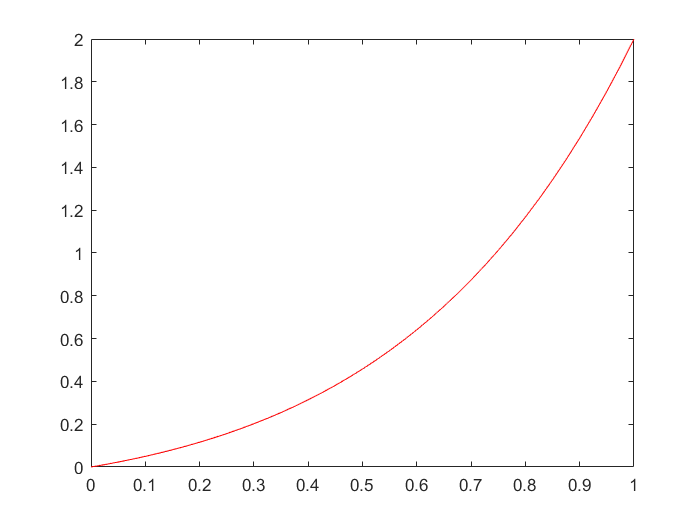

% Defining the parameters
n = 40;
a_e = 1;
b_e = 3;
c_e = 2;
h_e = 1/n;
k_e = (1/h_e)*[-1,1;1,-1]+(b_e/2)*[1,-1;1,-1]+((c_e*h_e)/6)*[2,1;1,2];
K = zeros(n+1,n+1);

%Creating the tridiagonal matrix

K(2:2+n:(n+1)*(n+1)) = k_e(2,1);
K(1:2+n:(n+1)*(n+1)) = k_e(2,2) + k_e(1,1);
K(1,1) = k_e(1,1);
K(n+2:n+2:(n+1)*(n+1)) = k_e(1,2);

K_new = zeros(n,n);
for i = 2:n+1
    for j = 2:n+1
       K_new(i-1,j-1) = K(i,j); 
    end
end

K_new(n,n-1) = 0;
K_new(n,n) = 1;

%Creating the F matrix 

F = zeros(n,1);
F(n,1) = 2;
U = (K_new)\F;
U_new = zeros(n+1,1);
U_new(1,1) = 0;
U_new(n+1,1) = 2;
for i = 2:n
    U_new(i,1) = U(i-1,1);
end

% Exact solution

x=0:(1/n):1;
Exact_solution = 2*(exp(2*x)-exp(x))/(exp(1)*(exp(1)-1));
y = [0:(1/n):1], plot(y,U_new), hold on, plot(y,Exact_solution,'r');



err = U_new - (Exact_solution)';
errn=norm(err,"inf");

% To check the order of convergence

% (log(((5.3935e-04)/(1.3480e-04))))/(log(2))
